# MHKiT WPTO Hindcast Example

This example demonstrates how to load and analyze data from the WPTO hindcast dataset hosted on AWS.

[WPTO Hindcast Dataset](https://registry.opendata.aws/wpto-pds-us-wave/)

## Dataset Description

The dataset consists of two main components:

**High-spatial-resolution dataset ('3-hour'):**

- Covers U.S. Exclusive Economic Zone (EEZ) along West coast and Hawaii

- Uses unstructured grid with ~200m resolution in shallow water

- 3-hour time step resolution

- Spans 32 years (01/01/1979 - 12/31/2010)

**Virtual buoy dataset ('1-hour'):**

- Available at specific locations within the spatial domain

- Spans same 32-year period

- 1-hour time resolution

## Available Variables

**3-hour Dataset Variables:**

Variables are indexed by latitude, longitude, and time:

- `energy_period`

- `maximum_energy_period`

- `mean_absolute_period`

- `mean_zero-crossing_period`

- `omni-directional_wave_power`

- `peak_period`

- `significant_wave_height`

- `water_depth`

- `spectral_width`

- `directionality_coefficient`

**1-hour Dataset Variables:**

Includes all variables from 3-hour dataset plus:

- `directional_wave_spectrum`

- `maximum_energy_direction`

- `mean_wave_direction`

- `frequency_bin_edges`

## Data Access Configuration

To access the WPTO hindcast data:

- Obtain API key from [https://developer.nrel.gov/signup/](https://developer.nrel.gov/signup/)

## Example 1: Request Single Location Data

Location: [PacWave South](https://www.energy.gov/eere/water/pacwave-offshore-wave-energy-test-site)

Request 3-hour significant wave height data for 1995 at PacWave South This example demonstrates basic data retrieval for a single parameter at one location

% Set parameters for data request
data_type = '3-hour';
year = 1995;
lat_lon = [44.624076, -124.280097]; % PacWave South
parameter = ["significant_wave_height"];  % Requested parameter
api_key = '3K3JQbjZmWctY0xmIfSYvYgtIcM3CN0cb1Y2w9bf';  % Demo API key (rate-limited)

% Request data for the specified location and time period
wave_data = request_wpto(data_type, parameter, lat_lon, year, api_key);

Reading from cache: https://developer.nrel.gov/api/hsds/?...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/g...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5


Plot significant wave height (Hm0) time-series

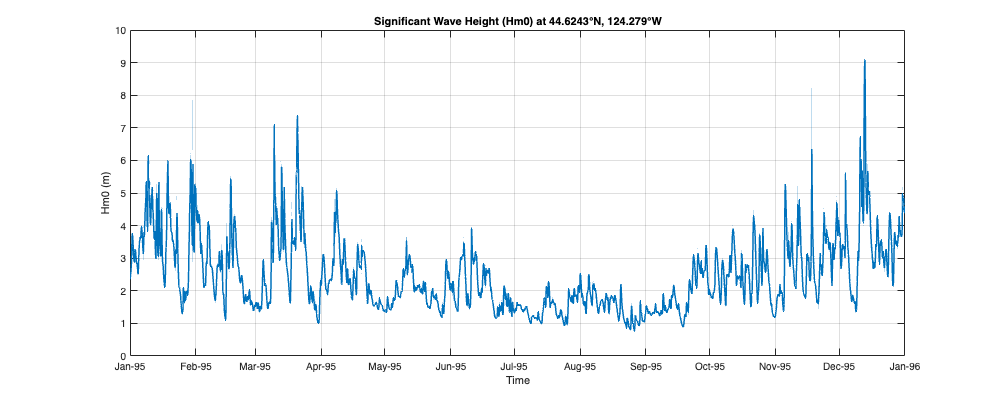

figure('Position', [100, 100, 1000, 400]);
plot(wave_data.time, wave_data.significant_wave_height, 'LineWidth', 1.5);
title(['Significant Wave Height (Hm0) at ' num2str(wave_data.metadata.latitude) '°N, ' ...
       num2str(-1 * wave_data.metadata.longitude) '°W']);
xlabel('Time');
ylabel('Hm0 (m)');
grid on;
xtickformat('MMM-yy');

## Example 2: Request Multiple Locations and Parameters

Locations:

- [PacWave South](https://www.energy.gov/eere/water/pacwave-offshore-wave-energy-test-site)

- [PacWave North](https://www.energy.gov/eere/water/pacwave-offshore-wave-energy-test-site)

Request 3-hour energy period and significant wave height at two locations This example shows how to handle multiple parameters and locations simultaneously

% Define multiple parameters and locations
parameter = ["energy_period", "significant_wave_height"];
lat_lon = [44.624076, -124.280097; % PacWave South
           43.489171, -125.152137]; % PacWave North

% Request data for both locations
wave_measurements = request_wpto(data_type, parameter, lat_lon, year, api_key);

Reading from cache: https://developer.nrel.gov/api/hsds/?...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/g...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...FWest_Coast%2FWest_Coast_wave_1995.h5


Create subplots for energy period and Hm0 at both locations

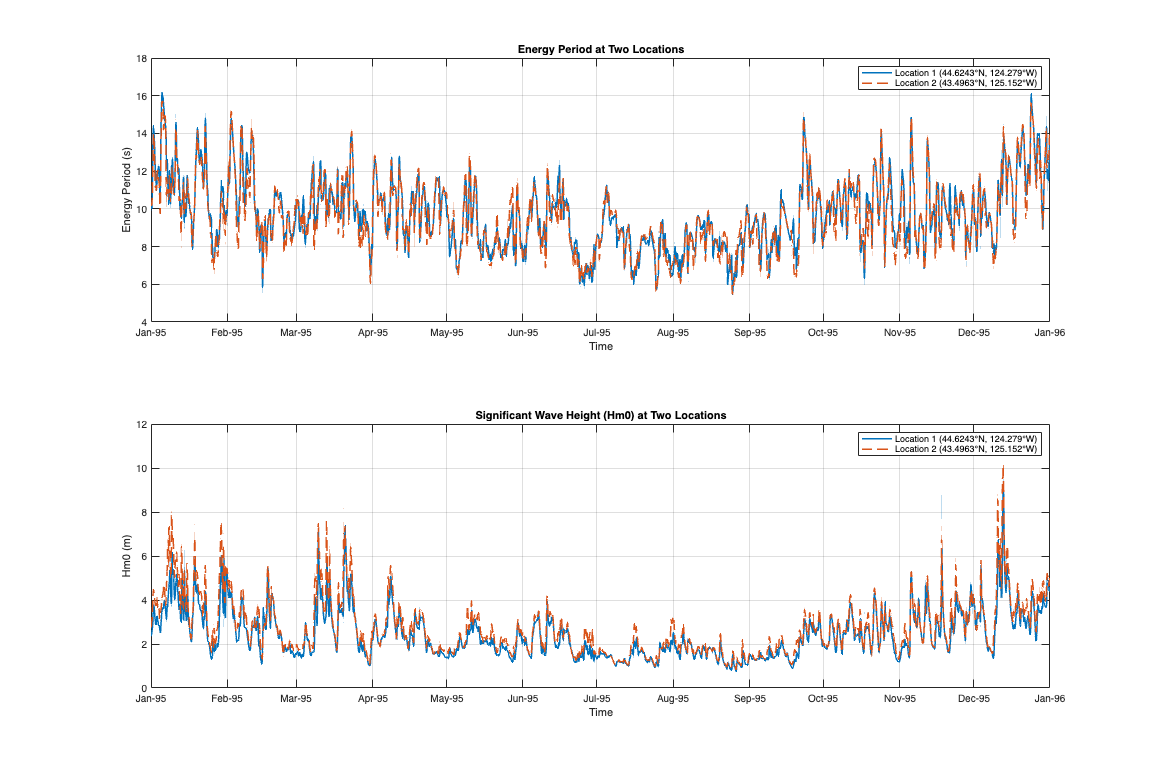

figure('Position', [100, 100, 1200, 800]);

% Plot Energy Period
subplot(2,1,1);
plot(wave_measurements(1).time, wave_measurements(1).energy_period, '-', 'LineWidth', 1.5);
hold on;
plot(wave_measurements(2).time, wave_measurements(2).energy_period, '--', 'LineWidth', 1.5);
hold off;
title('Energy Period at Two Locations');
xlabel('Time');
ylabel('Energy Period (s)');
grid on;
legend(['Location 1 (' num2str(wave_measurements(1).metadata.latitude) '°N, ' ...
        num2str(-1 * wave_measurements(1).metadata.longitude) '°W)'], ...
       ['Location 2 (' num2str(wave_measurements(2).metadata.latitude) '°N, ' ...
        num2str(-1 * wave_measurements(2).metadata.longitude) '°W)']);
xtickformat('MMM-yy');

% Plot Significant Wave Height
subplot(2,1,2);
plot(wave_measurements(1).time, wave_measurements(1).significant_wave_height, '-', 'LineWidth', 1.5);
hold on;
plot(wave_measurements(2).time, wave_measurements(2).significant_wave_height, '--', 'LineWidth', 1.5);
hold off;
title('Significant Wave Height (Hm0) at Two Locations');
xlabel('Time');
ylabel('Hm0 (m)');
grid on;
legend(['Location 1 (' num2str(wave_measurements(1).metadata.latitude) '°N, ' ...
        num2str(-1 * wave_measurements(1).metadata.longitude) '°W)'], ...
       ['Location 2 (' num2str(wave_measurements(2).metadata.latitude) '°N, ' ...
        num2str(-1 * wave_measurements(2).metadata.longitude) '°W)']);
xtickformat('MMM-yy');

## Example 3: Request High-Resolution 1-Hour Data

Location: [PacWave South](https://www.energy.gov/eere/water/pacwave-offshore-wave-energy-test-site)

Request 1-hour temporal resolution data including directional wave spectrum This example demonstrates working with high-resolution temporal data and spectral information

% Set parameters for 1-hour data request
data_type = '1-hour';                    % Using 1-hour dataset
parameter = ["peak_period", "omni-directional_wave_power"];
lat_lon = [44.624076, -124.280097]; % PacWave South

% Request high-resolution data
hourly_wave_data = request_wpto(data_type, parameter, lat_lon, year, api_key);

Reading from cache: https://developer.nrel.gov/api/hsds/?...ast%2FWest_Coast_virtual_buoy_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/g...ast%2FWest_Coast_virtual_buoy_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...ast%2FWest_Coast_virtual_buoy_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...ast%2FWest_Coast_virtual_buoy_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...ast%2FWest_Coast_virtual_buoy_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...ast%2FWest_Coast_virtual_buoy_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...ast%2FWest_Coast_virtual_buoy_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...ast%2FWest_Coast_virtual_buoy_1995.h5
Reading from cache: https://developer.nrel.gov/api/hsds/d...ast%2FWest_Coast_virtual_buoy_1995.h5


Plot peak period and omnidirectional wave power

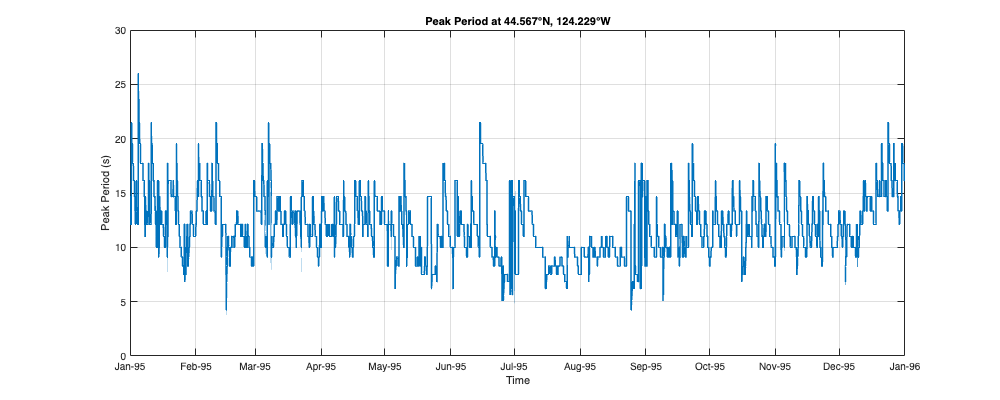

% Peak Period Plot
figure('Position', [100, 100, 1000, 400]);
plot(hourly_wave_data.time, hourly_wave_data.peak_period, 'LineWidth', 1.5);
title(['Peak Period at ' num2str(hourly_wave_data.metadata.latitude) '°N, ' ...
       num2str(-1 * hourly_wave_data.metadata.longitude) '°W']);
xlabel('Time');
ylabel('Peak Period (s)');
grid on;
xtickformat('MMM-yy');

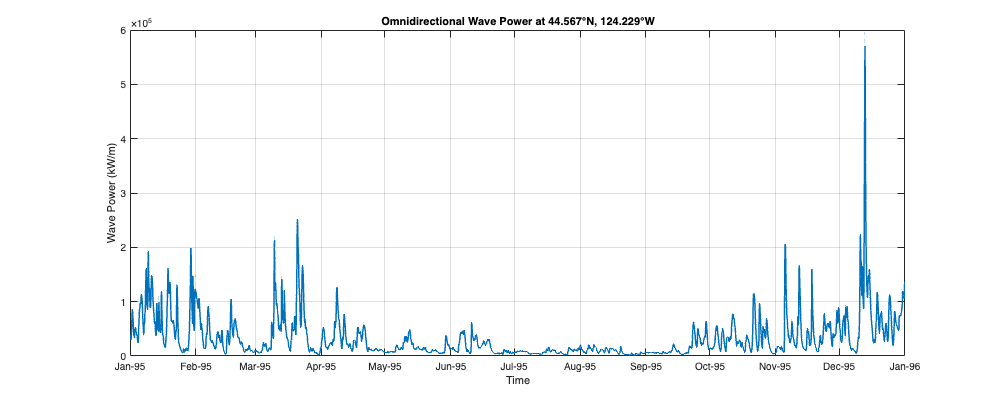


% Omnidirectional Wave Power Plot
figure('Position', [100, 100, 1000, 400]);
plot(hourly_wave_data.time, hourly_wave_data.omni_directional_wave_power, 'LineWidth', 1.5);
title(['Omnidirectional Wave Power at ' num2str(hourly_wave_data.metadata.latitude) '°N, ' ...
       num2str(-1 * hourly_wave_data.metadata.longitude) '°W']);
xlabel('Time');
ylabel('Wave Power (kW/m)');
grid on;
xtickformat('MMM-yy');